%clearing
clear;
clc;
close all;

manualdelta = 0.5; %range from 0 to 1, toggles delta shrinkage factor for shrinking of the covariance matrix
%excel file import
filename = 'fulldata.xlsx';
cdata = readmatrix(filename);
disp(size(cdata));

        2518          10



delta was calculated as 0, therefore manualdelta has been usen for shrinkage factor
Shrinkage Intensity Parameter (delta): 0.5
    0.1066    0.1066    0.1060    0.0977    0.0880    0.0584         0         0         0         0
    0.1045    0.0919    0.0787    0.0544    0.0280         0         0         0         0         0
    0.0887    0.1052    0.1216    0.1342    0.1458    0.1425    0.0935         0         0         0
    0.0264    0.0779    0.1299    0.1901    0.2513    0.3240    0.4180    0.5607    0.7643    1.0000
    0.0439    0.0852    0.1268    0.1737    0.2209    0.2711    0.3200    0.3419    0.2357         0
    0.1597    0.1265    0.0923    0.0417         0         0         0         0         0         0
    0.1801    0.1666    0.1525    0.1273    0.0996    0.0369         0         0         0         0
    0.1030    0.0500         0         0         0         0         0         0         0         0
    0.1412    0.1191    0.0962    0.0599    0.0204         0     

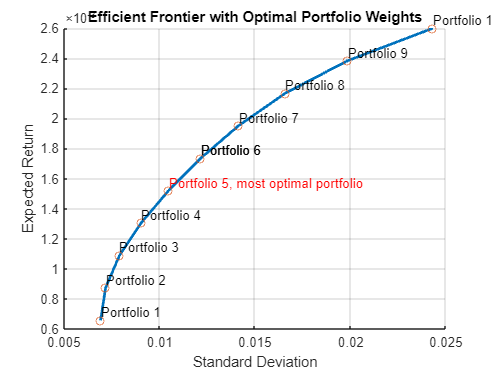

the optimal weightage for the 10 assets is
    0.0880
    0.0280
    0.1458
    0.2513
    0.2209
         0
    0.0996
         0
    0.0204
    0.1460




%profile on;
memoryBefore = memory;
[pwgt1, outsamples] = ldsmvo(cdata, manualdelta);

memoryAfter = memory;
%profile off;
%profile viewer;
disp(memoryAfter.MemUsedMATLAB - memoryBefore.MemUsedMATLAB);

     0




%test against outsample returns
outsampletest(pwgt1, outsamples);

         0    0.0778    0.1306    0.1901    0.2497    0.3093    0.3720    0.4347    0.5030    1.0000
         0         0         0         0         0         0         0         0         0         0
         0    0.0334    0.1041    0.1673    0.2306    0.2879    0.3442    0.4005    0.4505         0
    0.0181    0.0327    0.0348    0.0190    0.0031         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0
    0.3044    0.2958    0.2832    0.2628    0.2425    0.2148    0.1709    0.1270    0.0465         0
    0.4149    0.3833    0.3473    0.2969    0.2465    0.1881    0.1129    0.0377         0         0
         0         0         0         0         0         0         0         0         0         0
    0.1526    0.1229    0.1000    0.0638    0.0276         0         0         0         0         0
    0.1100    0.0541         0         0         0         0         0         0         0 